%% ================================================================
%    Ejercicio 2.2 — NMPC No Lineal con CasADi
%    TU Wien — Optimization-Based Control Methods SS2025
%    VERSION 2: seguimiento mejorado
%% ================================================================
clear; clc; close all;

addpath('C:\Users\PC\Downloads\Tesis\Codigo\watertank');
import casadi.*

%% ============================
% 1. Parametros fisicos (Tabla 1.1)
% ============================
p.Atank    = 1.539e-2;
p.rho      = 997.0;
p.eta      = 8.9e-4;
p.g        = 9.81;
p.alphao1  = 0.0583;   p.Do1 = 15e-3;
p.alphao2  = 0.1039;   p.A2  = 1.0429e-4;
p.alphao3  = 0.0600;   p.Do3 = 15e-3;
p.alpha120 = 0.3038;   p.D12 = 7.7e-3;  p.A12 = 0.55531e-4; p.lambdac12 = 24000;
p.alpha230 = 0.1344;   p.D23 = 15e-3;   p.A23 = 1.76715e-4; p.lambdac23 = 29600;
p.qmax     = 75e-6;
p.Ts       = 2;

%% ============================
% 2. Verificar estado estacionario para cada referencia
%    Esto nos dice si la referencia es alcanzable
% ============================
fprintf('=== Verificacion de estados estacionarios ===\n');

=== Verificacion de estados estacionarios ===


for h2_ref = [0.10, 0.25, 0.15]
    try
        xSol = fsolve(@(x) nl_ode([x(1); h2_ref; x(2)], [x(3); 0], p), ...
                      [h2_ref; h2_ref; 0.5], ...
                      optimoptions('fsolve','Display','off'));
        fprintf('  h2=%.2fm -> h=[%.4f %.4f %.4f] u1=%.4f\n', ...
            h2_ref, xSol(1), h2_ref, xSol(2), xSol(3));
    catch
        fprintf('  h2=%.2fm -> NO alcanzable\n', h2_ref);
    end
end

  h2=0.10m -> h=[0.2735 0.1000 0.0709] u1=0.6894
  h2=0.25m -> h=[0.6348 0.2500 0.1940] u1=1.0808
  h2=0.15m -> h=[0.3982 0.1500 0.1113] u1=0.8408



%% ============================
% 3. Punto de operacion en h2=0.25m (referencia mas alta)
% ============================
h2_op = 0.25;
xSol = fsolve(@(x) nl_ode([x(1); h2_op; x(2)], [x(3); 0], p), ...
              [h2_op; h2_op; 0.5], ...
              optimoptions('fsolve','Display','off'));
h1s = xSol(1); h3s = xSol(2); u1s = xSol(3);
p.xR = [h1s; h2_op; h3s];
p.uR = [u1s; 0];
fprintf('\nPunto de operacion h2=%.2fm:\n', h2_op);


Punto de operacion h2=0.25m:


fprintf('  h = [%.4f  %.4f  %.4f] m\n', h1s, h2_op, h3s);

  h = [0.6348  0.2500  0.1940] m


fprintf('  u = [%.4f  %.4f]\n', u1s, 0);

  u = [1.0808  0.0000]



%% ============================
% 4. Modelo CasADi (ODE no lineal) + RK4
% ============================
nx = 3; nu = 2; Ts = p.Ts;
eps_s = 1e-8;

x_s = casadi.SX.sym('x', nx);
u_s = casadi.SX.sym('u', nu);

h1 = x_s(1); h2 = x_s(2); h3 = x_s(3);
qi1 = p.qmax * u_s(1);
qi3 = p.qmax * u_s(2);

% Suavizado heights
h1p = (h1 + sqrt(h1^2 + eps_s)) / 2;
h2p = (h2 + sqrt(h2^2 + eps_s)) / 2;
h3p = (h3 + sqrt(h3^2 + eps_s)) / 2;

% Flujos outlet
qo1 = p.alphao1 * (p.Do1^2*pi/4) * sqrt(2*p.g*h1p);
qo2 = p.alphao2 * p.A2            * sqrt(2*p.g*h2p);
qo3 = p.alphao3 * (p.Do3^2*pi/4) * sqrt(2*p.g*h3p);

% Flujos coupling
dh12  = h1 - h2; abs12 = sqrt(dh12^2 + eps_s);
l12   = p.D12*p.rho/p.eta*sqrt(2*p.g*abs12);
a12   = p.alpha120*tanh(2*l12/p.lambdac12);
q12   = a12*p.A12*sqrt(2*p.g*abs12)*sign(dh12);

dh23  = h2 - h3; abs23 = sqrt(dh23^2 + eps_s);
l23   = p.D23*p.rho/p.eta*sqrt(2*p.g*abs23);
a23   = p.alpha230*tanh(2*l23/p.lambdac23);
q23   = a23*p.A23*sqrt(2*p.g*abs23)*sign(dh23);

xdot_s = [(qi1 - q12 - qo1)/p.Atank;
          (q12 - q23 - qo2)/p.Atank;
          (qi3 + q23 - qo3)/p.Atank];

f_cas  = casadi.Function('f', {x_s,u_s}, {xdot_s});
k1r    = f_cas(x_s, u_s);
k2r    = f_cas(x_s + Ts/2*k1r, u_s);
k3r    = f_cas(x_s + Ts/2*k2r, u_s);
k4r    = f_cas(x_s + Ts  *k3r, u_s);
F_rk4  = casadi.Function('F', {x_s,u_s}, {x_s + Ts/6*(k1r+2*k2r+2*k3r+k4r)});
cT     = [0 1 0];
fprintf('Modelo RK4 listo.\n');

Modelo RK4 listo.



%% ============================
% 5. Parametros NMPC
%    CLAVE: q grande, R1 pequeno = seguimiento agresivo
% ============================
N  = 30;
q  = 500;              % peso alto en error de salida
R1 = diag([0.1; 1.0]); % u1 libre, u3 penalizado (u3=0 en SS)
R2 = diag([0.1; 0.1]); % suavizado de cambios

xmin = [0;   0;   0  ];
xmax = [0.4; 0.4; 0.4];
umin = [0;   0  ];
umax = [1;   1  ];

fprintf('q=%g  R1=[%.2f %.2f]  N=%d\n', q, R1(1,1), R1(2,2), N);

q=500  R1=[0.10 1.00]  N=30



%% ============================
% 6. OCP — full discretization
% ============================
fprintf('Construyendo OCP...\n');

Construyendo OCP...



X_d  = casadi.SX.sym('X', nx, N+1);
U_d  = casadi.SX.sym('U', nu, N);
x0_p = casadi.SX.sym('x0', nx);
yr_p = casadi.SX.sym('yr');
up_p = casadi.SX.sym('up', nu);

J=0; g=[]; lbg=[]; ubg=[];

% Condicion inicial
g=[g; X_d(:,1)-x0_p]; lbg=[lbg;zeros(nx,1)]; ubg=[ubg;zeros(nx,1)];

for k = 1:N
    % Dinamica
    g=[g; X_d(:,k+1) - F_rk4(X_d(:,k), U_d(:,k))];
    lbg=[lbg; zeros(nx,1)];
    ubg=[ubg; zeros(nx,1)];

    % Salida y error
    yk = cT * X_d(:,k+1);
    ey = yk - yr_p;

    % Variacion control
    if k == 1
        du = U_d(:,1) - up_p;
    else
        du = U_d(:,k) - U_d(:,k-1);
    end

    % Costo con peso final aumentado (terminal cost)
    if k == N
        J = J + 10*q*ey^2 + U_d(:,k)'*R1*U_d(:,k) + du'*R2*du;
    else
        J = J +    q*ey^2 + U_d(:,k)'*R1*U_d(:,k) + du'*R2*du;
    end
end

w    = [reshape(X_d, nx*(N+1), 1); reshape(U_d, nu*N, 1)];
par_p = [x0_p; yr_p; up_p];
lbw  = [repmat(xmin, N+1, 1); repmat(umin, N, 1)];
ubw  = [repmat(xmax, N+1, 1); repmat(umax, N, 1)];

nlp  = struct('x',w,'f',J,'g',g,'p',par_p);
opts = struct;
opts.ipopt.print_level = 0;
opts.ipopt.max_iter    = 1000;
opts.ipopt.tol         = 1e-5;
opts.print_time        = 0;

solver_nmpc = casadi.nlpsol('solver_nmpc','ipopt',nlp,opts);
fprintf('Solver listo.\n');

Solver listo.



%% ============================
% 7. Test de convergencia (paso 3 del ejercicio)
% ============================
fprintf('\n--- Test convergencia ---\n');


--- Test convergencia ---


xk_t = [0.31; 0.15; 0.14];
yr_t = 0.10;
up_t = [0.6; 0.6];

w0_t = make_warm_start(xk_t, up_t, N, Ts, p, nx, nu, xmin, xmax);
sol_t = solver_nmpc('x0',w0_t,'lbx',lbw,'ubx',ubw,'lbg',lbg,'ubg',ubg,...
                    'p',[xk_t; yr_t; up_t]);
Ut = reshape(full(sol_t.x(nx*(N+1)+1:end)), nu, N);
fprintf('  u* = [%.4f  %.4f]  (uR = %.4f)\n', Ut(1,1), Ut(2,1), p.uR(1));

  u* = [0.0000  0.0000]  (uR = 1.0808)



%% ============================
% 8. Simulacion en bucle cerrado
% ============================
T_sim = 1200;
Nsim  = floor(T_sim/Ts);
t1    = floor(Nsim*0.33);
t2    = floor(Nsim*0.66);

yref_v = [0.10*ones(1,t1), 0.25*ones(1,t2-t1), 0.15*ones(1,Nsim-t2)];

% Condicion inicial: estado estacionario para h2=0.10
xSol0 = fsolve(@(x) nl_ode([x(1);0.10;x(2)],[x(3);0],p), ...
               [0.10;0.10;0.5], optimoptions('fsolve','Display','off'));
x_init = [xSol0(1); 0.10; xSol0(2)];
u_init = [xSol0(3); 0];

X_h = zeros(nx, Nsim+1); X_h(:,1) = x_init;
U_h = zeros(nu, Nsim);
T_h = (0:Nsim)*Ts;

uprev = u_init;
w0    = make_warm_start(x_init, u_init, N, Ts, p, nx, nu, xmin, xmax);

fprintf('\nSimulando %d pasos...\n', Nsim);


Simulando 600 pasos...


tic;
for k = 1:Nsim
    xk = X_h(:,k);
    yr = yref_v(k);

    sol  = solver_nmpc('x0',w0,'lbx',lbw,'ubx',ubw,'lbg',lbg,'ubg',ubg,...
                       'p',[xk; yr; uprev]);
    wopt = full(sol.x);

    Xtraj = reshape(wopt(1:nx*(N+1)),    nx, N+1);
    Utraj = reshape(wopt(nx*(N+1)+1:end), nu, N);

    uk        = min(umax, max(umin, Utraj(:,1)));
    U_h(:,k)  = uk;
    uprev     = uk;

    X_h(:,k+1) = max(0, min(0.55, rk4_m(xk, uk, Ts, p)));

    % Warm start desplazado
    Xw = [Xtraj(:,2:end), Xtraj(:,end)];
    Uw = [Utraj(:,2:end), Utraj(:,end)];
    w0 = [reshape(Xw, nx*(N+1),1); reshape(Uw, nu*N,1)];

    if mod(k,50)==0
        fprintf('  t=%5.0fs | h2=%.3fm | ref=%.3fm | u=[%.3f %.3f] | %.0fs\n',...
            k*Ts, X_h(2,k+1), yr, uk(1), uk(2), toc);
    end
end

  t=  100s | h2=0.100m | ref=0.100m | u=[0.557 0.101] | 1s
  t=  200s | h2=0.100m | ref=0.100m | u=[0.571 0.103] | 2s
  t=  300s | h2=0.100m | ref=0.100m | u=[0.572 0.104] | 3s
  t=  400s | h2=0.101m | ref=0.250m | u=[1.000 1.000] | 3s
  t=  500s | h2=0.237m | ref=0.250m | u=[0.965 0.363] | 5s
  t=  600s | h2=0.248m | ref=0.250m | u=[0.713 0.301] | 7s
  t=  700s | h2=0.248m | ref=0.250m | u=[0.713 0.301] | 8s
  t=  800s | h2=0.246m | ref=0.150m | u=[0.000 0.000] | 9s
  t=  900s | h2=0.154m | ref=0.150m | u=[0.836 0.155] | 10s
  t= 1000s | h2=0.150m | ref=0.150m | u=[0.701 0.140] | 11s
  t= 1100s | h2=0.150m | ref=0.150m | u=[0.683 0.136] | 12s
  t= 1200s | h2=0.150m | ref=0.150m | u=[0.682 0.136] | 13s


fprintf('Total: %.1fs\n', toc);

Total: 12.5s


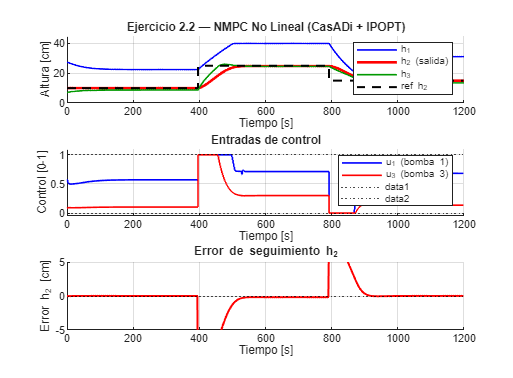


%% ============================
% 9. Graficas
% ============================
figure('Name','Ej 2.2 NMPC v2','Position',[50 50 950 700]);

subplot(3,1,1); hold on; grid on;
plot(T_h, X_h(1,:)*100,'b','LineWidth',1.2,'DisplayName','h_1');
plot(T_h, X_h(2,:)*100,'r','LineWidth',2.0,'DisplayName','h_2 (salida)');
plot(T_h, X_h(3,:)*100,'Color',[0 .6 0],'LineWidth',1.2,'DisplayName','h_3');
stairs(T_h(1:end-1), yref_v*100,'k--','LineWidth',1.5,'DisplayName','ref h_2');
ylabel('Altura [cm]'); xlabel('Tiempo [s]');
title('Ejercicio 2.2 — NMPC No Lineal (CasADi + IPOPT)');
legend('Location','northeast'); ylim([0 45]);

subplot(3,1,2); hold on; grid on;
stairs(T_h(1:end-1), U_h(1,:),'b','LineWidth',1.2,'DisplayName','u_1 (bomba 1)');
stairs(T_h(1:end-1), U_h(2,:),'r','LineWidth',1.2,'DisplayName','u_3 (bomba 3)');
yline(1,'k:'); yline(0,'k:');
ylabel('Control [0-1]'); xlabel('Tiempo [s]');
title('Entradas de control');
legend('Location','northeast'); ylim([-0.05 1.1]);

subplot(3,1,3); hold on; grid on;
e = X_h(2,1:Nsim) - yref_v;
plot(T_h(1:Nsim), e*100,'r','LineWidth',1.5);
yline(0,'k:');
ylabel('Error h_2 [cm]'); xlabel('Tiempo [s]');
title('Error de seguimiento h_2');
ylim([-5 5]);


%% ================================================================
% FUNCIONES AUXILIARES
%% ================================================================

function w0 = make_warm_start(x0, u0, N, Ts, p, nx, nu, xmin, xmax)
    Xw = zeros(nx, N+1); Xw(:,1) = x0;
    for i = 1:N
        Xw(:,i+1) = max(xmin, min(xmax, rk4_m(Xw(:,i), u0, Ts, p)));
    end
    w0 = [reshape(Xw, nx*(N+1),1); repmat(u0, N, 1)];
end

function xn = rk4_m(x, u, dt, p)
    k1 = nl_ode(x,           u, p);
    k2 = nl_ode(x+dt/2*k1,  u, p);
    k3 = nl_ode(x+dt/2*k2,  u, p);
    k4 = nl_ode(x+dt*k3,    u, p);
    xn = x + dt/6*(k1+2*k2+2*k3+k4);
end

function f = nl_ode(h, u, p)
    h1 = max(0,h(1)); h2 = max(0,h(2)); h3 = max(0,h(3));
    qi1 = p.qmax*u(1); qi3 = p.qmax*u(2);
    qo1 = p.alphao1*(p.Do1^2*pi/4)*sqrt(2*p.g*(h1+1e-10));
    qo2 = p.alphao2*p.A2          *sqrt(2*p.g*(h2+1e-10));
    qo3 = p.alphao3*(p.Do3^2*pi/4)*sqrt(2*p.g*(h3+1e-10));
    dh12=h1-h2;
    l12=p.D12*p.rho/p.eta*sqrt(2*p.g*abs(dh12)+1e-10);
    a12=p.alpha120*tanh(2*l12/p.lambdac12);
    q12=a12*p.A12*sqrt(2*p.g*abs(dh12)+1e-10)*sign(dh12+1e-15);
    dh23=h2-h3;
    l23=p.D23*p.rho/p.eta*sqrt(2*p.g*abs(dh23)+1e-10);
    a23=p.alpha230*tanh(2*l23/p.lambdac23);
    q23=a23*p.A23*sqrt(2*p.g*abs(dh23)+1e-10)*sign(dh23+1e-15);
    f=[(qi1-q12-qo1)/p.Atank;
       (q12-q23-qo2)/p.Atank;
       (qi3+q23-qo3)/p.Atank];
end